# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

This tutorial walks you through converting fake data for a hypothetical extracellular electrophysiology experiment to Neurodata Without Borders (NWB). It is recommended that you start with the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), as this tutorial picks up where that one left off. The types of data we will convert are:

- Electrodes table

- Voltage recording

- Local field potential (LFP)

- Spike times

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in a `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), similar to the trials table in the previous section. `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrode table

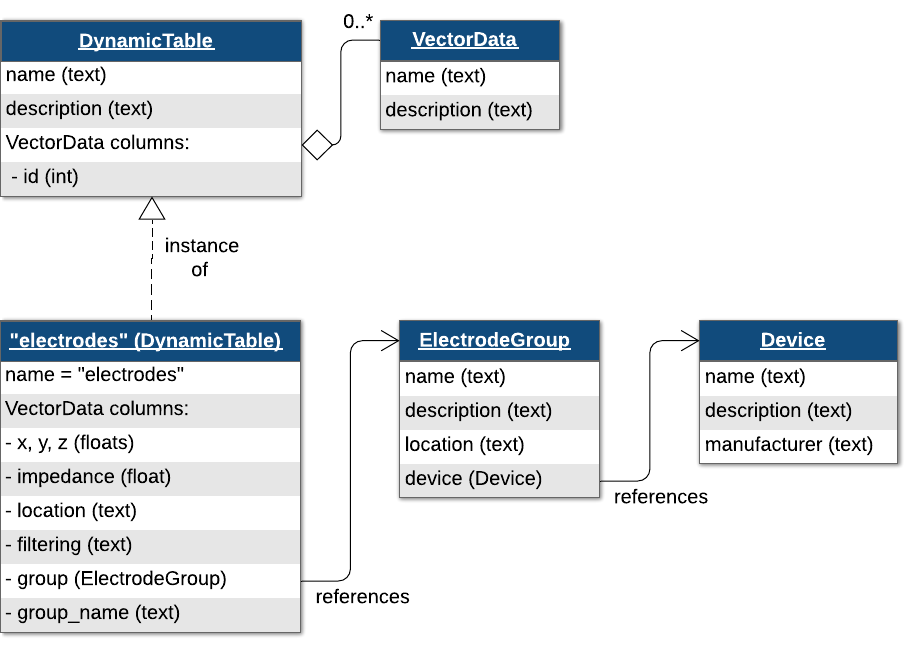

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html)s, by first creating a [MATLAB native `Table`](https://www.mathworks.com/help/matlab/ref/table.html) object and then calling `util.table2nwb` to convert this [`Table`](https://www.mathworks.com/help/matlab/ref/table.html) object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

nshanks = 4;
nchannels_per_shank = 3;
variables = {'x', 'y', 'z', 'imp', 'location', 'filtering', 'group', 'label'};
tbl = cell2table(cell(0, length(variables)), 'VariableNames', variables);
device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', device);
for ishank = 1:nshanks
    electrode_group = types.core.ElectrodeGroup( ...
        'description', ['electrode group for shank' num2str(ishank)], ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    nwb.general_extracellular_ephys.set(['shank' num2str(ishank)], electrode_group);
    group_object_view = types.untyped.ObjectView(electrode_group);
    for ielec = 1:nchannels_per_shank
        electrode_label = ['shank' num2str(ishank) 'elec' num2str(ielec)];
        tbl = [...
            tbl; ...
            {5.3, 1.5, 8.5, NaN, 'unknown', 'unknown', group_object_view, electrode_label} ...
        ];
    end
end
tbl
electrode_table = util.table2nwb(tbl, 'all electrodes');
nwb.general_extracellular_ephys_electrodes = electrode_table;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...

tbl = 12×8 table
     x      y      z     imp     location       filtering                 group                      label     
    ___    ___    ___    ___    ___________    ___________    ______________________________    _______________

    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    [1×1 types.untyped.ObjectView]    {'shank1elec1'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    [1×1 types.untyped.ObjectView]    {'shank1elec2'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    [1×1 types.untyped.ObjectView]    {'shank1elec3'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    [1×1 types.untyped.ObjectView]    {'shank2elec1'}
    5.3    1.5    8.5    NaN    {'unkn

    'table', types.untyped.ObjectView(electrode_table), ...
    'description', 'all electrodes', ...
    'data', (0:height(tbl)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

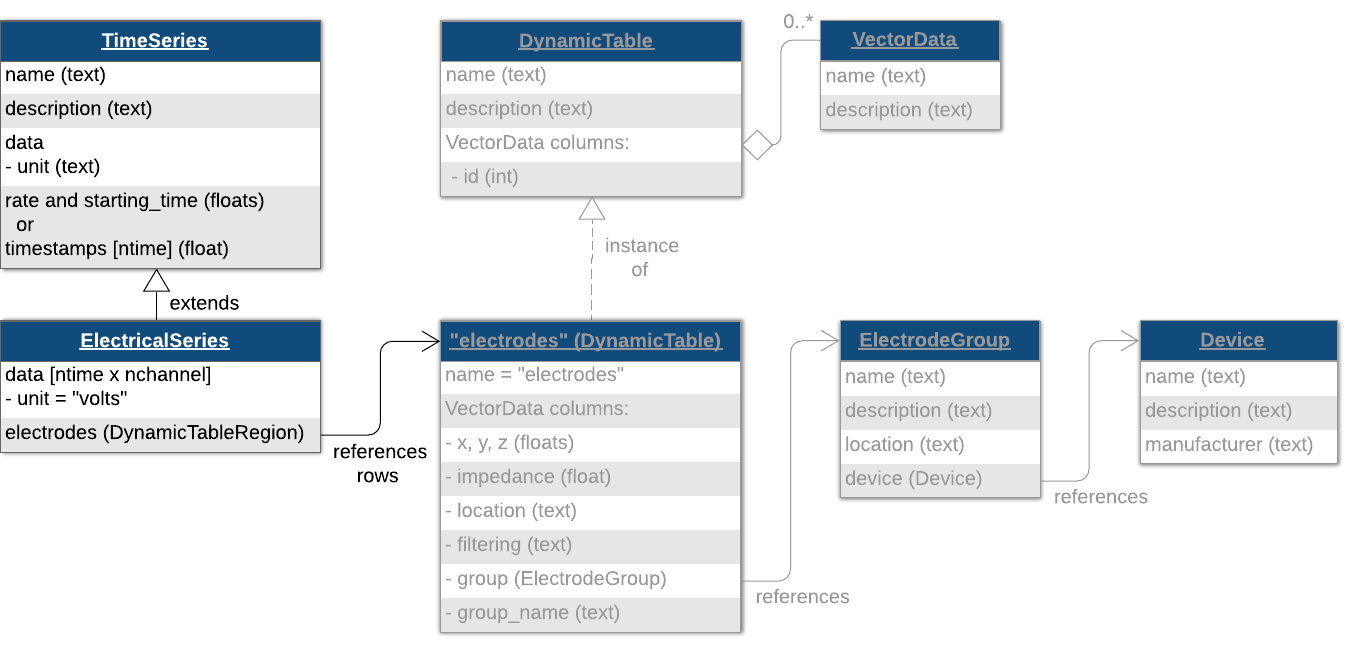

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` in the previous section.

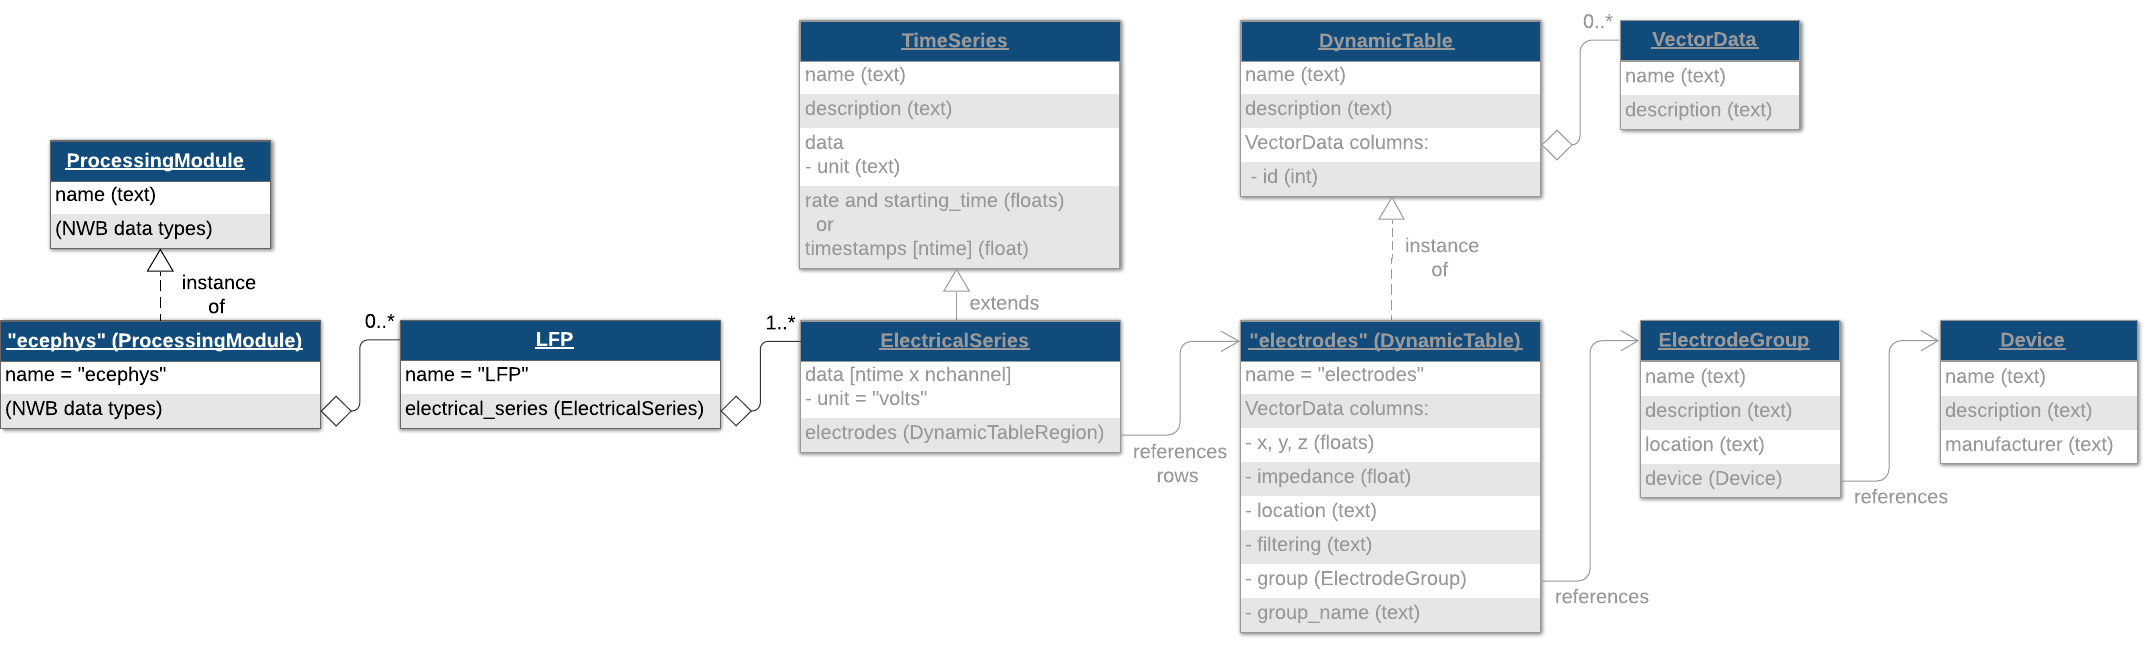

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike times

#### Ragged arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for ishank = 1:num_cells
    spikes{ishank} = [];
    for iunit = 1:poissrnd(20)
        spikes{ishank}(end+1) = cumsum(exprnd(1/firing_rate));
    end
end
spikes

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

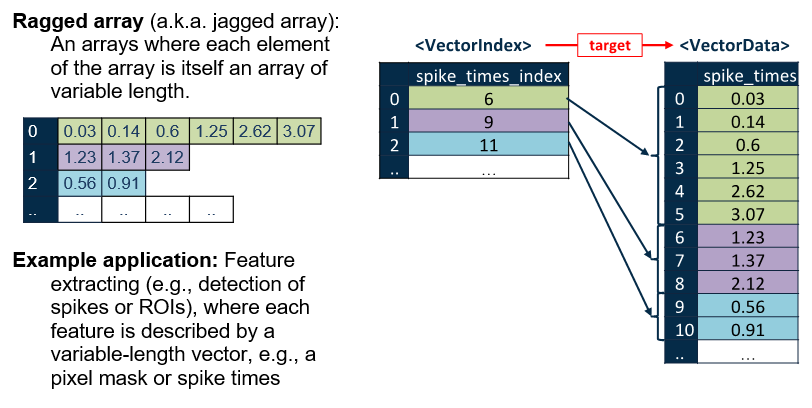

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

spikes = 1×10 cell array
    {1×28 double}    {1×25 double}    {1×22 double}    {1×23 double}    {1×18 double}    {1×21 double}    {1×18 double}    {1×29 double}    {1×15 double}    {1×20 double}



nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(0:length(spikes) - 1) ...
    ), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Write the file

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB data

Data arrays are read passively from the file. Calling [`TimeSeries.data`](TimeSeries.datahttps://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing data regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =     0.3238    0.0568    0.1861   -1.0841    0.4015    1.5673    0.5038    0.9148    0.6305   -1.8499
   -0.2572    1.1631   -0.2843   -2.0889   -0.6124   -0.0981   -0.1522   -0.6394   -1.9411    0.2052
   -1.0528   -0.1458    0.1278    1.6205    1.2195   -0.3119    0.8782   -0.0532   -0.5970    1.4307
   -1.3472   -1.0314   -0.7384    0.0003    1.1219    0.0319   -1.0600    0.4216   -1.6961    0.5677
   -0.5865    2.4174   -0.6169   -0.6104   -0.8354   -0.3832    0.4795   -1.4911    0.3497   -0.2414



% You can use the utility function |util.read_indexed_column| to read the
% spike times of a specific unit.
util.read_indexed_column( ...
    nwb.units.spike_times_index, nwb.units.spike_times, 1)

ans =     0.0192
    0.0151
    0.0079
    0.0401
    0.0393
    0.0343
    0.0657
    0.0066
    0.0230
    0.0292


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)